format long
time1 = [0, 11, 22, 34]; 
pres1 = [8.1, 32.2, 56.2, 79.9];
vol1 = [120, 119.8, 119.6, 119.4];
time2 = [68, 119, 170, 221, 255];
pres2 = [95.3, 115, 125.1, 126.3, 112.9];
vol2 = [115.1, 105.3, 85.4, 70.7, 55.8];
time3 = [272, 280, 289, 297];
pres3 = [90.6, 70, 50.1, 30.6];
vol3 = [50.7, 49.7, 49.5, 49.2];
time4 = [331, 425, 510, 578, 646];
pres4 = [13.5, 8.4, 6.2, 5.1, 7.5]';
vol4 = [50, 64.3, 79.7, 94.1, 109];
n = [0 1 2 3 4];
c = intpolc(pres2,vol2)

c =    1.0e+02 *

   1.151000000000000  -0.004974619289340  -0.000494239966701  -0.000277511042190   0.000065965936005


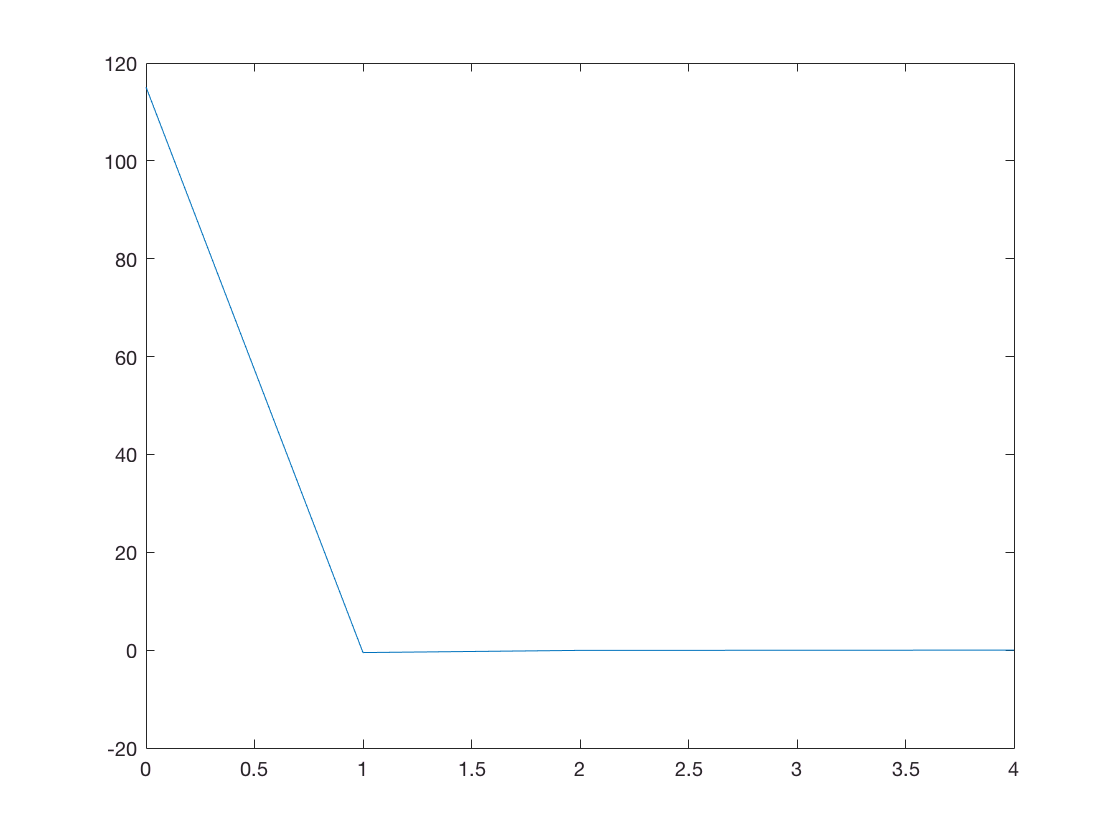

plot(n,c)

pval = NestedM(c,pres2,vol2)

pval =    1.0e+04 *

   0.010716472675408  -0.020443703342687   0.356716626632162   2.346231386624065   7.987974356307533


cint = divdif(pres2,vol2);

c =    1.0e+02 *

   1.151000000000000                -Inf   0.854000000000000   0.707000000000000   0.558000000000000


c =    1.0e+02 *

   1.151000000000000                -Inf                 NaN   0.707000000000000   0.558000000000000


c =    1.0e+02 *

   1.151000000000000                -Inf                 NaN                 NaN   0.558000000000000


c =    1.0e+02 *

   1.151000000000000                -Inf                 NaN                 NaN                 NaN


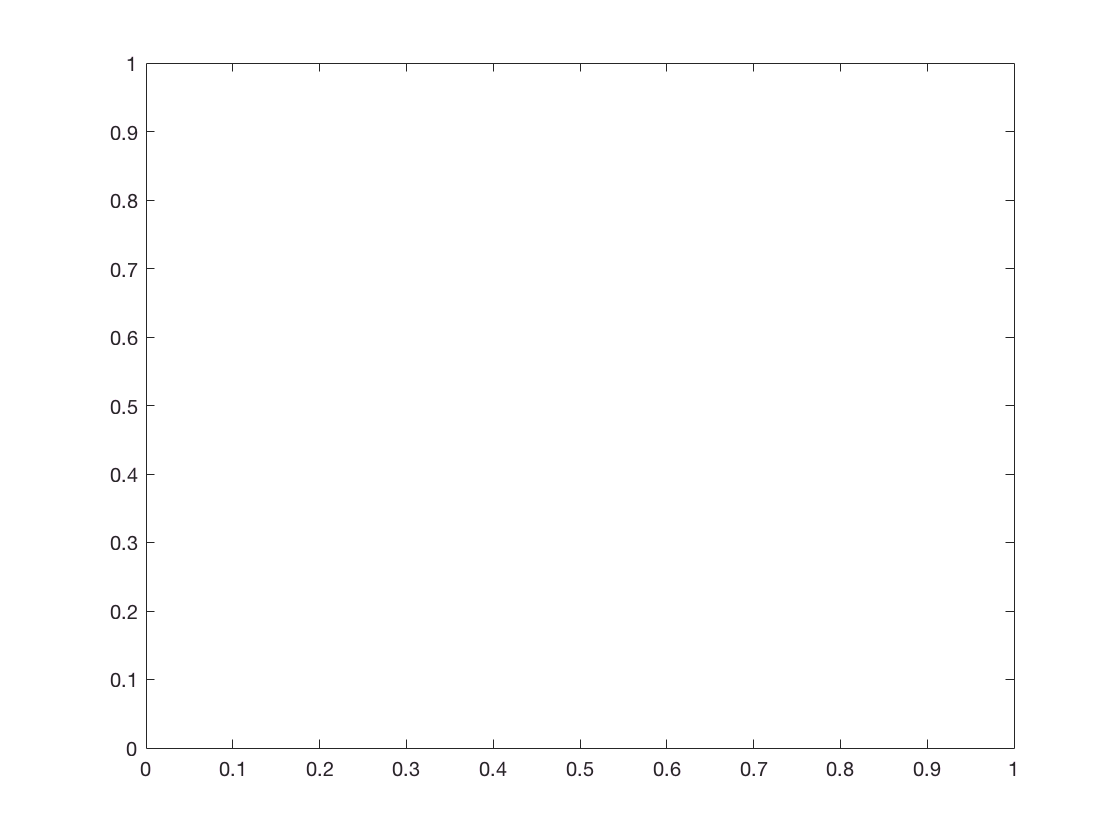

xn = linspace(0,6,200);
pval = NestedM(cint,pres2,xn);
plot(xn,pval);

wn = vol2;
plot(xn,wn-pval,xn,pval);

Matrix dimensions must agree.